load MotorX_NoControl.mat
t_X_NC = out.tout;
input_X_NC = out.simout;
error_X_NC = out.simout1;
CE_X_NC = out.simout2;
offset = -0.5

offset = -0.5000

output_X_NC = out.simout3-offset;

CE_X_NC = (11.4/255)*CE_X_NC;


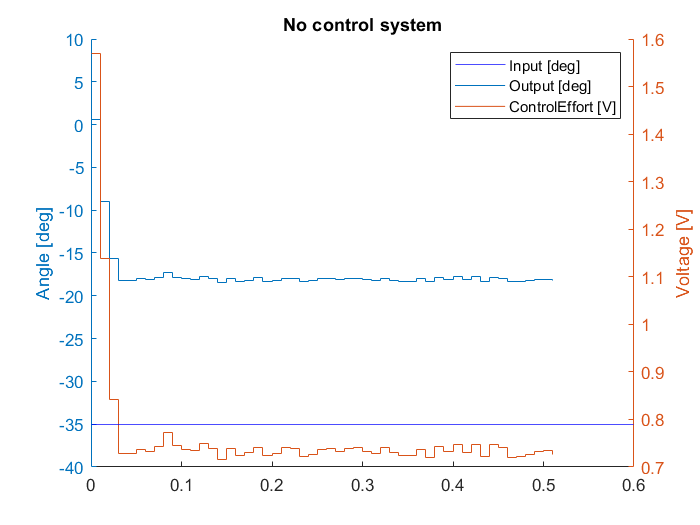

clf;
hold on
yyaxis left
yline(-35,'b')
plot(output_X_NC)
ylabel('Angle [deg]')
ylim([-40 10])


yyaxis right
plot(CE_X_NC)
ylabel('Voltage [V]')

title('No control system')
legend('Input [deg]','Output [deg]','ControlEffort [V]')

hold off